# Transferencia de calor en superficies extendidas de área transversal variable

Carlos Arturo Ibarra Muñoz 

Estudiante de Mastria en ingenieria 

2023-I

## Parte A

## Deducciones de los perfiles de temperatura, flux de conduccion, calor y eficiencia de superficies extendidas de area transversal variable

1). Deducción superficie extendida triangular 

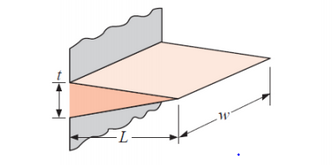

2). Deducción superficie extendida triangular parabólica 

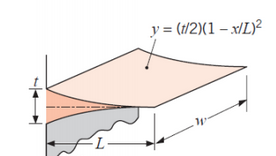

3). Deducción superficie extendida circular retctangular 

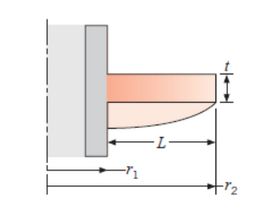

4). Deducción superficie extendida circular triangular 

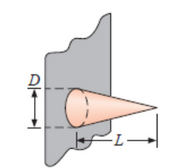

5). Deducción superficie extendida circular  parabólica 

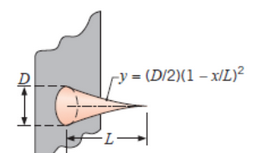

## Parte B 

## Codigos

En esta seccion se presentan laas graficas de los perfiles de temperatura, flux y la geometria de la superficie extendida 

Selección de la geometría 

Superficie extendida triangular


m = 2.0509

Efi = 0.4229

Qf = 8.2483e+03

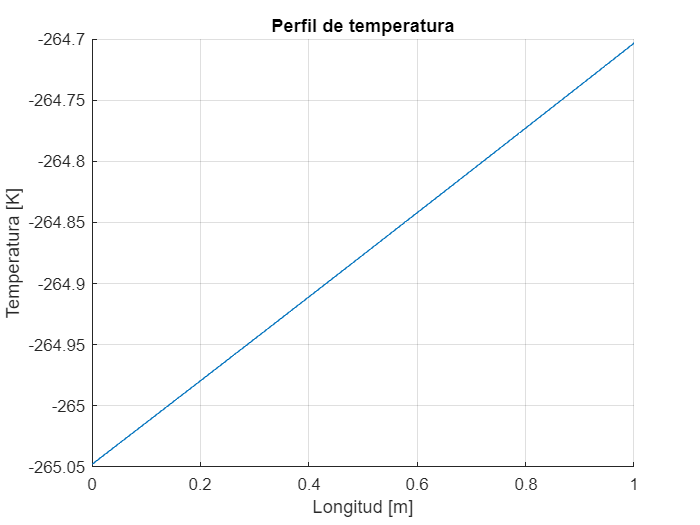

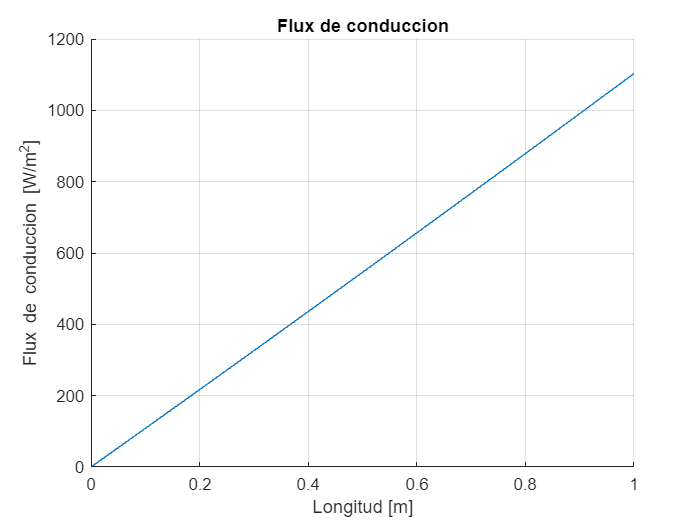

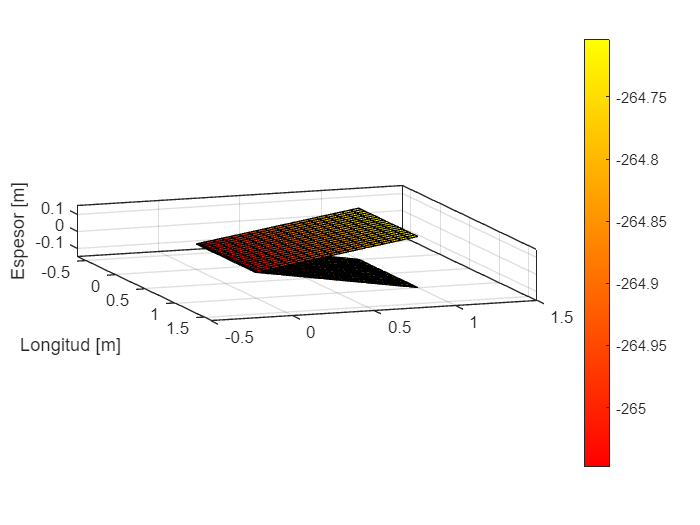

Efi = 0.4229

Qf = 8.2483e+03

Aleta = 11

clc
clear all
Geo=11;
format short

[Aleta] = superficie(Geo)

- (Geo = 11) Geometría rectangular triangular

- (Geo = 12) Geometría rectangular parabólica 

- (Geo = 13) Geometría rectangular circular

- (Geo = 14) Geometría pin triangular

- (Geo = 15) Geometría pin triangular parabólico

function [Aleta] = superficie(Geometria);

Seleccion de dimeciones

Para una superficie extendía triangular y triangular parabólica 

L=1; %[m]
w=1; %[m]
t=0.3; %[mm]

 Para una superficie extendía triangular y triangular parabólica 

r2= 8 ; %[m]
r1= 5; %[m]
tc = 3 ; %[m]

Geometría pin triangular y pin triangular parabolico

D    =5 ; %[m]
Long =10; %[m]


Seleccion de material

- (Material = 1)  Cobalto

- (Material = 2)  Cobalto puro 

- (Material = 3)  Oro

- (Material = 4)  Plata

- (Material = 5)  Paladio

Material = 3 ;

Seleccion de paametros termicos

h    = 200  ; %[w/m^2*K]
Tinf = 273.15;     %[K]
Tb   = 100;   %[K]


if Geometria == 11
    disp('Superficie extendida triangular')
    [Efi,Qf] = superficieTri(L,w,t,Material,h,Tb,Tinf)
    Aleta = 11;
elseif Geometria == 12
    disp('Superficie extendida triangular parabolica')
    [Efi,Qf] = superficieTri_para(L,w,t,Material,h,Tb,Tinf)
     Aleta = 12;
elseif Geometria == 13
     disp('Sección Circular rectangular')
     [Efi,Qf] = superficieRec_cir(r1,r2,tc,Material,h,Tb,Tinf)
     Aleta = 13;
elseif Geometria == 14
     disp('Sección Circular Conica')
     [Efi] = superficiePin_Tri(D,Long,Material,h,Tb,Tinf)
     Aleta = 14; 
elseif Geometria == 15
     disp('Sección Circular Conica Parabolica')
     [Efi,Qf] = superficiePin_Tri_Para(D,Long,Material,h,Tb,Tinf)
     Aleta = 15;
end
end


Superficie extendida triangular



function [Efi,Qf] = superficieTri(L,w,t,Material,h,Tb,Tinf)
if Material == 1
    k=99.2; %[W/m^2 K]
elseif Material == 2
    k=401;  %[W/m^2 K]
elseif Material == 3
    k=317;  %[W/m^2 K]
elseif Material == 4
    k=429;  %[W/m^2 K]
elseif Material == 5
    k=71.8; %[W/m^2 K]
end
%Eficiencia
m=((2*h)/(k*t)).^(1/2)
mL=2*m*L;
Io_mL=besseli(0,mL);
I1_mL=besseli(1,mL);
Efi=(I1_mL/((m*(L))*Io_mL))
%Calor 
Qf=((k*Tb*I1_mL)/(Io_mL))*w*t %[W]

es=20;                  %Numero de datos de los vectores
x=linspace(0,L,es);      
w1=linspace(0,w,es);
A=zeros(length(w1));
% Perfil de temperatura
mL2=2*m*(((L/100)*x).^(1/2));
Io_mL2=besseli(0,mL2);
I1_mL2=besseli(1,mL2);
Teta=(Tb)*((Io_mL2)/(Io_mL)) - Tinf;
[Teta1] = meshgrid(Teta,Teta);
figure (1)
grid on
hold on
plot(x,Teta)
xlabel('Longitud [m]')
ylabel('Temperatura [K]')
title ('Perfil de temperatura')
%Flux de conducion
Flux=(k.*Tb.*m.*((L.*x).^(1/2)).*I1_mL2)./(Io_mL);
figure (2)
grid on
hold on
plot(x,Flux)
xlabel('Longitud [m]')
ylabel('Flux de conduccion [W/m^2]')
title ('Flux de conduccion')

for i=1:length(x)
    T(i)=(t/2).*(x(i)./L);
    A(i,:)=x;
end
figure (3)
hold on
[TT,W1]=meshgrid(T,w1);
surf(W1,A,TT,Teta1,'FaceColor','flat')
colormap('autumn')
colorbar
axis equal
xx=linspace(0,L,es);
ww=linspace(0,w,es);
AA=zeros(length(ww));
for j=1:length(xx)
    T1(j)=(-t/2).*(xx(j)./L);
    AA(j,:)=xx;
end
[TT1,WW]=meshgrid(T1,ww);
surf(WW,AA,TT1,Teta1,'FaceColor','flat')
colormap('autumn')
colorbar
axis equal

hold on
box on
grid on
axis equal
view([70 10])
xlabel('Longitud [m]')
zlabel('Espesor [m]')
end


Superficie extendida triangular parabolica

function [Efi,Qf] = superficieTri_para(L,w,t,Material,h,Tb,Tinf)
if Material == 1
    k=99.2; %[W/m^2 K]
elseif Material == 2
    k=401;  %[W/m^2 K]
elseif Material == 3
    k=317;  %[W/m^2 K]
elseif Material == 4
    k=429;  %[W/m^2 K]
elseif Material == 5
    k=71.8; %[W/m^2 K]
end
%Eficiencia
m=sqrt((2*h)/(k*t));
mL=m*L;
Io_mL=besseli(0,mL);
I1_mL=besseli(1,mL);
Efi= (2)/(1+(sqrt(1+4*((mL)^2))))
%Calor
Qf=(Tb*k*w*t*(-1+sqrt(1+4*(m*L)^(2))))/(2*L)
es=20;               %Numero de datos de los vectores
x=linspace(0,L,es);
w1=linspace(0,w,es);
A=zeros(length(w1));
% Perfil de temperatura
r_1 = (-1+(sqrt(1+4*((mL)^2))));
Teta=(Tb)*((x.^r_1)/(L.^r_1)) - Tinf;
Teta1=meshgrid(Teta,Teta);
figure (1)
grid on
hold on
plot(x,Teta)
xlabel('Longitud [m]')
ylabel('Temperatura [K]')
title ('Perfil de temperatura')
%Flux de conducion
Flux=(k*Tb*r_1)*((x.^r_1-1)/(L.^r_1));
figure (2)
grid on
hold on
plot(x,Flux)
xlabel('Longitud [m]')
ylabel('Flux de conduccion [W/m^2]')
title ('Flux de conduccion')

for i=1:length(x)
    T(i)=(t/2).*(x(i)./L).^2;
    A(i,:)=x;
end
figure (3)
hold on
[TT,W1]=meshgrid(T,w1);
surface(W1,A,TT,Teta1,'FaceColor','flat')
colormap('autumn')
colorbar
axis equal
xx=linspace(0,L,es);
ww=linspace(0,w,es);
AA=zeros(length(ww));
for j=1:length(xx)
    T1(j)=(-t/2).*(xx(j)./L).^2;
    AA(j,:)=xx;
end
[TT1,WW]=meshgrid(T1,ww);
surface(WW,AA,TT1,Teta1,'FaceColor','flat')
colormap('autumn')
colorbar
axis equal
hold on
box on
grid on
axis equal
view([70 10])
xlabel('Longitud [m]')
zlabel('Espesor [mm]')
end

Superficie extendida circular rectangular 

function [Qf,Efi] = superficieRec_cir(r1,r2,tc,Material,h,Tb,Tinf)
if Material == 1
    k=99.2; %[W/m^2 K]
elseif Material == 2
    k=401;  %[W/m^2 K]
elseif Material == 3
    k=317;  %[W/m^2 K]
elseif Material == 4
    k=429;  %[W/m^2 K]
elseif Material == 5
    k=71.8; %[W/m^2 K]
end
esp=20;                           %Numero de datos de los vectores
r=linspace(r1,r2,esp);
theta=linspace(0,2*pi,esp);
x =cos(theta')*r;
y =sin(theta')*r;
zo=0;
z=repmat(zo, size(x));
%Eficiencia
m=sqrt((2*h)/(k*tc))
r2c = r2+(tc/2);
mr1 = m*r1
mr2c= m*r2c
c2  = ((2*r1))/(m*((r2c^2)-(r1^2)))
Io_mr1  = besseli(0,mr1);
I1_mr1  = besseli(1,mr1);
I1_mr2c = besseli(1,mr2c);
Ko_mr1  = besselk(0,mr1);
K1_mr1  = besselk(1,mr1);
K1_mr2c = besselk(1,mr2c);
Efi= (c2)*(((K1_mr1*I1_mr2c)-(I1_mr1*K1_mr2c))/((Io_mr1*K1_mr2c)+(I1_mr2c*Ko_mr1)))
%Calor
Qf = ((2*pi*k*tc*r1))*((K1_mr1*I1_mr2c-I1_mr1*K1_mr2c)/(Io_mr1*K1_mr2c+I1_mr2c*Ko_mr1))
%Perfil de temperatura
mr = m*r;
Io_mr = besseli(0,mr);
I1_mr = besseli(1,mr);
Ko_mr = besselk(0,mr);
K1_mr = besselk(1,mr);
C1 = (Tb*K1_mr2c)/(Io_mr1*K1_mr2c + I1_mr2c*Ko_mr1);
C2 = C1*((I1_mr2c)/(K1_mr2c));
Teta = C1*Io_mr + C2*Ko_mr - Tinf
Teta1=meshgrid(Teta,Teta);
figure (1)
grid on
hold on
plot(r,Teta)
xlabel('Radio [m]')
ylabel('Temperatura [K]')
title ('Perfil de temperatura')
%Flux de conduccion 
Flux = -(m*Tb)*((I1_mr*K1_mr2c-K1_mr*I1_mr2c)/(Io_mr1*K1_mr2c+I1_mr2c*Ko_mr1))
figure (2)
grid on
hold on
plot(r,Flux)
xlabel('Radio [m]')
ylabel('Flux de conduccion [W/m^2]')
title ('Flux de conduccion')
figure (3)
hold on
axis equal
surf(x,y,z,Teta1,'FaceColor','flat')
colormap('autumn')
colorbar
zo=tc;
z=repmat(zo, size(x));
surf(x,y,z,Teta1,'FaceColor','flat')
colormap('autumn')
colorbar
[X,Y,Z]=cylinder(r2);
Z = Z*tc;
surf (X,Y,Z,'FaceColor','red')
[X,Y,Z]=cylinder(r1);
Z = 5*Z*tc;
surf (X,Y,Z,'FaceColor','yellow')
title('Sección Circular rectangular')
grid on
box on
hold on
xlabel('Diámetro [m]')
zlabel('Espesor [mm]')
view([30 18])
end

Superficie extendida pin triangular

function [Efi,Qf] = superficiePin_Tri(D,Long,Material,h,Tb,Tinf)
if Material == 1
    k=99.2; %[W/m^2 K]
elseif Material == 2
    k=401;  %[W/m^2 K]
elseif Material == 3
    k=317;  %[W/m^2 K]
elseif Material == 4
    k=429;  %[W/m^2 K]
elseif Material == 5
    k=71.8; %[W/m^2 K]
end
esp=25;                            %Numero de datos de los vectores
r=linspace(0,D/2,esp);
Angf= pi/3;
Al=linspace(0,Long,esp);
% Eficiencia 
m=sqrt((4*h)/(k*D));
mL = 2*m*Long;
I1_mL  = besseli(0,mL);
I2_mL  = besseli(2,mL);
Efi= (2/(m*Long))*((I2_mL)/(I1_mL))
%Calor
Qf=((k*D*pi*m)/(4))*((I2_mL)/(I1_mL))
%Prefil de temperatur
mLz   =2*m*sqrt(Long*Al);
I2_mLz= besseli(2,mLz);
Teta = (Tb*(sqrt(Long))*(Al.^(-0.5))).*((I2_mLz)/(I1_mL))-Tinf;
Teta1=meshgrid(Teta,Teta);
figure (1)
grid on
hold on
plot(Al,Teta)
xlabel('Longitud [m]')
ylabel('Temperatura [K]')
title ('Perfil de temperatura')
%Flux de conduccion 
Flux = (Tb*Long*m*I2_mLz)./(Al*I1_mL);
figure (2)
grid on
hold on
plot(Al,Flux)
xlabel('Longitud [m]')
ylabel('Flux de conduccion [W/m^2]')
title ('Flux de conduccion')
figure (3)
Pfi=linspace(0,2*pi,esp);
[r,Pfi]=meshgrid(r,Pfi);
x=r.*cos(Pfi)*sin(Angf);
y=r.*sin(Pfi)*sin(Angf);
zz=Al;
z11=meshgrid(zz,zz);
surf(x,y,-z11,Teta1,'facecolor','flat')
colormap('autumn')
colorbar
axis equal
title('Sección Triángular variable')
grid on
box on
hold on
ylabel('Diametro [L]')
zlabel('Longitud [mm]')
end

Superficie extendida pin triangular parabolico  %%%% organizar falta 

function [Efi,Qf] = superficiePin_Tri_Para(D,Long,Material,h,Tb,Tinf)
if Material == 1
    k=99.2; %[W/m^2 K]
elseif Material == 2
    k=401;  %[W/m^2 K]
elseif Material == 3
    k=317;  %[W/m^2 K]
elseif Material == 4
    k=429;  %[W/m^2 K]
elseif Material == 5
    k=71.8; %[W/m^2 K]
end
esp=25;                        %Numero de datos de los vectores
r=linspace(0,Long,esp);
Angf= pi/3;
x=linspace(0,Long,esp);
%Eficiencia
m=sqrt((4*h)/(k*D));
mL=m*Long;
Io_mL=besseli(0,mL);
I1_mL=besseli(1,mL);
Efi= (2)/(1+(sqrt(1+(4/9)*((m*Long)^2))))
%Calor
Qf=((Tb*pi*(D.^2))/(8*Long))*((-3+sqrt(9+4*(m*Long)^(2))))
% Perfil de temperatura
r_1 = (-3+(sqrt(9+4*((m*Long)^2))))/(2);
Teta=(Tb)*((x.^r_1)/(Long.^r_1));
Teta1=meshgrid(Teta,Teta);
figure (1)
grid on
hold on
plot(x,Teta)
xlabel('Longitud [m]')
ylabel('Temperatura [K]')
title ('Perfil de temperatura')
%Flux de conducion
Flux=(k*Tb*r_1)*((x.^r_1-1)/(Long.^r_1));
figure (2)
grid on
hold on
plot(x,Flux)
xlabel('Longitud [m]')
ylabel('Flux de conduccion [W/m^2]')
title ('Flux de conduccion')
figure (3)
yfun=(D/2).*((x./Long)).^2;
Pfi=linspace(0,2*pi,esp);
[y,Pfi]=meshgrid(yfun,Pfi);
X=y.*cos(Pfi)*sin(Angf);
Y=y.*sin(Pfi)*sin(Angf);
z=r;
z11=meshgrid(z,z);
surf(X,Y,z11,Teta1,'facecolor','flat')
colormap('autumn')
colorbar
axis equal
title('Sección Parabólica variable')
grid on
box on
hold on
ylabel('Diametro [L]')
zlabel('Longitud [m]')


end